% CONTROL DATA:
% close all, clc;
 
% N1 = round(96); % number of elements
% trials = 500;
% lambdaMax = lambda5g;
% lambdaMin = lambda10g;
% L = arrSize * lambdaMin; % Aperture size
% controlData = cell([500 6]);
% 
% for i = 1:trials-1
%     % generate pos such that spacing is dAvg = lambdaMin/2 (Symmetric along 0)
%     % DIST #1: Uniform Random Distribution (Symmetric along 0)
%     % pos = unifrnd(0,L/2,[1 N1/2]); % uniform distribution x := [0,L/2]
%     % pos = [-pos pos];
%     
%     % DIST #2: Uniform Random Distribution (NOT Symmetric)
%     pos = unifrnd(-L/2,L/2,[1 N1]); % uniform distribution x := [-L/2,L/2]
%     
%     pos = sort(pos);
%     spacing = gradient(pos); % interelement spacing
%     arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);pos;zeros(1,N1)]);
%     
%     % save full 10g plot
%     plot10g = pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%          'CoordinateSystem','rectangular','Type','powerdb');
%     figs(7) = {figure};
%     plot10g = polarpattern(plot10g);
%     set(figs{7},'Visible','off') % 'on' to turn back on.
%     
%     % save full 5g plot
%     plot5g = pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
%         'CoordinateSystem','rectangular','Type','powerdb');
%     figs(8) = {figure};
%     plot5g = polarpattern(plot5g);
%     set(figs{8},'Visible','off') % 'on' to turn back on.
%     
%     plot10g = findLobes(plot10g);
%     controlData(i,1) = {plot10g.sideLobes.magnitude};
%     controlData(i,2) = {plot10g.sideLobes.angle};
%     controlData(i,3) = {plot10g.HPBW};
%     
%     plot5g = findLobes(plot5g);
%     controlData(i,4) = {plot5g.sideLobes.magnitude};
%     controlData(i,5) = {plot5g.sideLobes.angle};
%     controlData(i,6) = {plot5g.HPBW};
% end

% ELEMENT REDUCTION:
% close all, clc;
%  
% N1 = 96; % number of elements
% trials = 5;
% lambdaMax = lambda5g;
% lambdaMin = lambda10g;
% L = arrSize * lambdaMin; % Aperture size
% elementData = cell([500 2]);
% index = 1;
% 
% for i = 1:N1
%     N1 = i; % thin number of elements
%     for j = 1:trials-1
%         % generate pos such that spacing is dAvg = lambdaMin/2 (Symmetric along 0)
%         % DIST #1: Uniform Random Distribution (Symmetric along 0)
%         % pos = unifrnd(0,L/2,[1 N1/2]); % uniform distribution x := [0,L/2]
%         % pos = [-pos pos];
%         
%         % DIST #2: Uniform Random Distribution (NOT Symmetric)
%         pos = unifrnd(-L/2,L/2,[1 N1]); % uniform distribution x := [-L/2,L/2]
%         
%         pos = sort(pos);
%         spacing = gradient(pos); % interelement spacing
%         arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);pos;zeros(1,N1)]);
%         
%         % save full 10g plot
%         plot10g = pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%              'CoordinateSystem','rectangular','Type','powerdb');
%         figs(7) = {figure};
%         plot10g = polarpattern(plot10g);
%         set(figs{7},'Visible','off') % 'on' to turn back on.
%         
%         % save full 5g plot
%         plot5g = pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
%             'CoordinateSystem','rectangular','Type','powerdb');
%         figs(8) = {figure};
%         plot5g = polarpattern(plot5g);
%         set(figs{8},'Visible','off') % 'on' to turn back on.
%         
%         plot10g = findLobes(plot10g);
%         elementData(index,1) = {plot10g};
% %         elementData(index,1) = {plot10g.sideLobes.magnitude};
% %         elementData(index,2) = {plot10g.sideLobes.angle};
% %         elementData(index,3) = {plot10g.HPBW};
%         
%         plot5g = findLobes(plot5g);
%         elementData(index,2) = {plot5g};
% %         elementData(index,4) = {plot5g.sideLobes.magnitude};
% %         elementData(index,5) = {plot5g.sideLobes.angle};
% %         elementData(index,6) = {plot5g.HPBW};
%         
%         index = index + 1;
%     end
% end

% close all, clc;
% % Control Data
% mag10g = [controlData{:,1}];
% ang10g = [controlData{:,2}];
% hpbw10g = [controlData{:,3}];
% % histogram(mag10g)
% % histogram(ang10g)
% % histogram(hpbw10g)
% 
% mag5g = [controlData{:,4}];
% ang5g = [controlData{:,5}];
% hpbw5g = [controlData{:,6}];
% % histogram(mag5g)
% % histogram(ang5g)
% % histogram(hpbw5g)
% 
% % save full 10g plot
% uni10g = pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%      'CoordinateSystem','rectangular','Type','powerdb');
% figs(7) = {figure};
% uni10g = polarpattern(uni10g(200:1600));
% set(figs{7},'Visible','off') % 'on' to turn back on.
% uni10g = findLobes(uni10g);
% uni10g = ones([1 384])*uni10g.HPBW;
% 
% % save full 5g plot
% uni5g = pattern(d{6},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
%      'CoordinateSystem','rectangular','Type','powerdb');
% figs(8) = {figure};
% uni5g = polarpattern(uni5g);
% set(figs{8},'Visible','off') % 'on' to turn back on.
% uni5g = findLobes(uni5g);
% uni5g = ones([1 384])*uni5g.HPBW;
% 
% hpbw10g = zeros([1 384]);
% sidmag10g = zeros([1 384]);
% hpbw5g = zeros([1 384]);
% sidmag5g = zeros([1 384]);
% for i = 1:384
%     cell10g = elementData{i,1};
%     cell5g = elementData{i,2};
%     cell10g.sideLobes;
%     if isempty(cell10g.sideLobes.magnitude) && isempty(cell5g.sideLobes.magnitude)
%         hpbw10g(1,i) = cell10g.HPBW;
%         sidmag10g(1,i) = 0;
%         hpbw5g(1,i) = cell5g.HPBW;
%         sidmag5g(1,i) = 0;
%     else
%         hpbw10g(1,i) = cell10g.HPBW;
%         sidmag10g(1,i) = cell10g.sideLobes.magnitude;
%         hpbw5g(1,i) = cell5g.HPBW;
%         sidmag5g(1,i) = cell5g.sideLobes.magnitude;
%     end
%             
% end
% 
% figure
% hold on;
% plot(sidmag10g(1:4:384),'k-')
% plot(sidmag5g(1:4:384),'r--')
% title(['Sidelobe Levels v. Num Elements']);
% xlabel('Number of Elements');
% ylabel('Sidelobe Levels (dB)');
% legend(['10GHz'],['5GHz'],'Location','northeast');
% hold off;
% 
% figure
% hold on;
% plot(hpbw10g(5:4:384))
% plot(uni10g(5:4:384),'--')
% plot(hpbw5g(5:4:384))
% plot(uni5g(5:4:384),'--')
% title(['Half Power Beamwidth v. Num Elements']);
% xlabel('Number of Elements (starting @ 5 elements)');
% ylabel('Half Power Beamwidth (degrees)')
% legend(['Random 10GHz'],['Uniform 10GHz BW'],['Random 5GHz'],['Uniform 5GHz BW'],'Location','northeast');
% hold off;

% % Advanced Analysis: ULA Animation
% close all, clc
% h = figure;
% axis tight manual % this ensures that getframe() returns a consistent size
% filename = 'ULA_96.gif';
% theta0 = -90:5:90;
% 
% for n = 1:size(theta0,2)
%     % Calculate weight corrections to steer each freq.
%     wd10 = steervec(getElementPosition(d{5})/lambda10g,theta0(1,n));
%     wd5 = steervec(getElementPosition(d{6})/lambda5g,theta0(1,n));
%     
%     subplot(2,2,1:2)
%     pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%          'CoordinateSystem','rectangular','Type','powerdb','Weights',wd10);
%     title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
%     legend(['Non-Uniform (dAvg ~= lambda10g, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'], ...
%         'Location','south');
%     xlim([-90 90]);
%     ylim([-45 5]);
%     
%     subplot(2,2,3:4)
%     pattern(d{6},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
%         'CoordinateSystem','rectangular','Type','powerdb','Weights',wd5);
%     title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
%     legend(['Non-Uniform Array (dAvg ~= lambda5g/2, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'], ...
%         'Location','south');
%     xlim([-90 90]);
%     ylim([-45 5]);
%     drawnow;
%       % Capture the plot as an image 
%       frame = getframe(h); 
%       im = frame2im(frame); 
%       [imind,cm] = rgb2ind(im,256); 
%       % Write to the GIF File 
%       if n == 1 
%           imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
%       else 
%           imwrite(imind,cm,filename,'gif','WriteMode','append'); 
%       end 
% end
% 
% RLA Animation
% close all, clc
% h = figure;
% axis tight manual % this ensures that getframe() returns a consistent size
% % filename = ['RLA_Non-Symmetric_',num2str(N1),'.gif'];
% % filename = ['RLA_Symmetric_',num2str(N1),'.gif'];
% filename = ['RLA_Gen',num2str(N1),'.gif'];
% theta0 = -90:5:90;
% 
% for n = 1:size(theta0,2)
%     % Calculate weight corrections to steer each freq.
%     wd10 = steervec(getElementPosition(arr)/lambda10g,theta0(1,n));
%     wd5 = steervec(getElementPosition(arr)/lambda5g,theta0(1,n));
%     
%     subplot(2,2,1:2)
%     pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%          'CoordinateSystem','rectangular','Type','powerdb','Weights',wd10);
%     title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
%     legend(['Non-Uniform (dAvg ~= lambda10g, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'], ...
%         'Location','south');
%     xlim([-90 90]);
%     ylim([-45 5]);
%     
%     subplot(2,2,3:4)
%     pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
%         'CoordinateSystem','rectangular','Type','powerdb','Weights',wd5);
%     title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
%     legend(['Non-Uniform Array (dAvg ~= lambda5g/2, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'], ...
%         'Location','south');
%     xlim([-90 90]);
%     ylim([-45 5]);
%     drawnow;
%       % Capture the plot as an image 
%       frame = getframe(h); 
%       im = frame2im(frame); 
%       [imind,cm] = rgb2ind(im,256); 
%       % Write to the GIF File 
%       if n == 1 
%           imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
%       else 
%           imwrite(imind,cm,filename,'gif','WriteMode','append'); 
%       end 
% end

% close all, clc
% % all elements reside in a space 0cm->21cm (Aperture)
% % end points for both arrays are the same!
% % lambdaMin-> d = lambda... lambdaMax-> d = lambda/2 
% N1 = 96 % number of elements
% lambdaMin = lambda10g
% L =  (N1 - 1) * lambdaMin % Aperture size
% 
% % maybe unecessary
% theta0 = [0:5:30]; % scan angle
% wd = steervec(getElementPosition(arr)/lambda5g,theta0);
% 
% % generate pos such that spacing is dAvg = lambdaMin/2 (symmetric along 0)
% pos = [-L/2:lambda10g:L/2]
% 
% normal5g = zeros([2 N1]);
% arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);pos;zeros(1,N1)],'ElementNormal',normal5g);
% 
% figure(2)
% hold on;
% pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
%      'CoordinateSystem','rectangular','Type','powerdb','Weights',wd);
% % pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
% %     'CoordinateSystem','rectangular','Type','powerdb','Weights',wd);
% hold off;

% Inital Problem Statement:
d = cell([6 1]); % store all ULA configs
figs = cell([15 1]); % store all figures
arrSize = 96; % number of antenna elements in array
c = physconst('LightSpeed');

% 5GHz signal
fc5g = 5e9;
lambda5g = c / fc5g;

% 10GHz signal
fc10g = 10e9;
lambda10g = c / fc10g;

% NON-CONSTANT APERTURE
% Ideal response! Try to mimick this response in following topologies
% plot 5GHz ULA (d = lambda5g/2) (Aperture = 0.48m)
sArr = phased.ULA(arrSize,lambda5g/2);
d(1) = {sArr};
% plot 10GHz ULA (d = lambda10g/2) (Aperture = 0.24m)
sArr = phased.ULA(arrSize,lambda10g/2);
d(2) = {sArr};

% Aperture Size
postion5g = getElementPosition(d{1});
len5g = round(100*(postion5g(2,length(postion5g)) - postion5g(2,1)),2)
postion10g = getElementPosition(d{2});
len10g = round(100*(postion10g(2,length(postion10g)) - postion10g(2,1)),2)

figs(1) = {figure};
hold on;
pattern(d{1},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
pattern(d{2},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
title('Non-Constant Aperture d = lambda/2')
legend(['Aperture(5GHz) = ',num2str(len5g),'cm'], ...
    ['Aperture(10GHz) = ',num2str(len10g),'cm'],'Location','south')
ylim([-45 5]); xlim([-90 90]);
hold off;

% #1 CONSTANT APERTURE (10GHz -> d = lambda10g/2; 5GHz -> d = lambda5g/4)
% NO GRATING LOBES 
% (NA solution; Half-Power Beamwidth is too large large (not directed),
% sidelobe levels are too long)
figs(2) = {figure};
sArr = phased.ULA(arrSize,lambda10g/2);
d(3) = {sArr};
sArr = phased.ULA(arrSize,lambda5g/4); % d < lambda/2 HPBW is too fat
d(4) = {sArr};

% Aperture Size
postion5g = getElementPosition(d{3});
len5g = round(100*(postion5g(2,length(postion5g)) - postion5g(2,1)),2)
postion10g = getElementPosition(d{4});
len10g = round(100*(postion10g(2,length(postion10g)) - postion10g(2,1)),2)

figs(3) = {figure};
hold on;
pattern(d{3},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
pattern(d{4},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
title(['Constant Aperture = ',num2str(len5g),'cm'])
legend(['d(10GHz) = lambda/2'],['d(5GHz) = lambda/4'],'Location','south')
ylim([-45 5]); xlim([-90 90]);
hold off;

% #2 CONSTANT APERTURE (10GHz -> d = lambda10g; 5GHz -> d = lambda5g/2)
% NO GRATING LOBES (fix this)
figs(3) = {figure};
sArr = phased.ULA(arrSize,lambda10g);
d(5) = {sArr};
sArr = phased.ULA(arrSize,lambda5g/2);
d(6) = {sArr};

% Aperture Size
postion5g = getElementPosition(d{5});
len5g = round(100*(postion5g(2,length(postion5g)) - postion5g(2,1)),2)
postion10g = getElementPosition(d{6});
len10g = round(100*(postion10g(2,length(postion10g)) - postion10g(2,1)),2)

figs(4) = {figure};
hold on;
pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
pattern(d{6},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
title(['Constant Aperture = ',num2str(len5g),'cm'])
legend(['d(10GHz) = lambda'],['d(5GHz) = lambda/2'],'Location','south')
ylim([-45 5]); xlim([-90 90]);
hold off;

% NVM
uni10g = pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');
uni5g = pattern(d{6},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb');

% TESTBENCH: RANDOMIZED ARRAYS
close all, clc
N1 = round(96); % number of elements
lambdaMax = lambda5g;
lambdaMin = lambda10g;
L = arrSize * lambdaMin; % Aperture size

% maybe unecessary
% theta0 = 0; % scan angle
% B = lambdaMax/lambdaMin % beamwidth param
% steerability = 1 + sin(theta0) % steerability param
% dMin = lambdaMax/2 % min spacing in randomized array (so lambda5g works!)
% w0 = 1.5;
% dAvg = w0 * dMin / (B * steerability) % avg inter element spacing

% generate pos such that spacing is dAvg = lambdaMin/2 (Symmetric along 0)
% DIST #1: Uniform Random Distribution (Symmetric along 0)
pos = unifrnd(0,L/2,[1 N1/2]); % uniform distribution x := [0,L/2]
pos = [-pos pos];

% DIST #2: Uniform Random Distribution (NOT Symmetric)
% pos = unifrnd(-L/2,L/2,[1 N1]); % uniform distribution x := [-L/2,L/2]

% DIST #3: Normal Distribution (dAvg = lambdaMin/2, dMin = lambdaMax/2)
% dAvg = lambdaMin/2;
% dVar = lambdaMax/2;
% pd = makedist('Normal','mu',dAvg,'sigma',dVar)
% pos = random(pd, [1 N1]);

% DIST #4: OTHER
% pos = unifrnd(0,1,[1 48]) * 200*lambdaMin;
% pos = [-pos pos];
% len = sort(pos)
% len = pos(1,96) - pos(1,1)

pos = sort(pos);

spacing = gradient(pos); % interelement spacing

% check distance metrics for pos
test_L = round(100*(pos(1,N1) - pos(1,1)),2)

test_dAvg = mean(spacing)
theo_dAvg = lambdaMin/2

test_dMin = 2*min(spacing)
theo_dMin = lambdaMax

N1 = 96;
% x position
xpos = zeros(1,N1);
xpos(1:2:N1) = patchElement.Length;
xpos(2:2:N1) = -patchElement.Length;

% Best position
best = sort(GlobalBest.Position)
best = best(1:N1);

% Microstrip Array construction
Marr = phased.ConformalArray('Element',patchElement,'ElementPosition', [xpos' best' zeros(1,N1)']);


arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);pos;zeros(1,N1)]);

% Calculate Half-Power Beamwidth
dBdown = -10;

% Calculate the steering vectors for lookout directions
% theta0 = [-30:5:30]; % scan angle
theta0 = 0; % scan angle
wd = steervec(getElementPosition(arr)/lambda5g,theta0);
cover = 20; % plot coverage angle

figs(5) = {figure};
subplot(2,2,1:2)
hold on;
% save full 10g plot
pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)
pattern(d{5},fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform (dAvg ~= lambda10g, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'],...
    ['Uniform (d = lambda10g/2, N =',num2str(arrSize),', Aperture = ',num2str(len10g),'cm)'], ...
    'Location','south');
ylim([-40 5]);
hold off;

% ZOOMED FIGURE: 10G
subplot(2,2,3:4)
hold on;
pattern(arr,fc10g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)
pattern(d{5},fc10g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform (dAvg ~= lambda10g, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'],...
    ['Uniform (d = lambda10g/2, N =',num2str(arrSize),', Aperture = ',num2str(len10g),'cm)'], ...
    'Location','south');
xlim([-cover cover]); ylim([-40 5]);
hold off;

figs(6) = {figure};
subplot(2,2,1:2)
hold on;
% save full 5g plot
pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb','Weights',wd);
pattern(d{6},fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform Array (dAvg ~= lambda5g/2, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'],...
    ['Uniform Array (d = lambda5g/2, N =',num2str(arrSize),', Aperture = ',num2str(len5g),'cm)'], ...
    'Location','south');
ylim([-40 5]);
hold off;

% ZOOMED FIGURE: 5G
subplot(2,2,3:4)
hold on;
pattern(arr,fc5g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)
title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform Array (dAvg ~= lambda5g/2, N = ',num2str(N1),', Aperture = ',num2str(test_L),'cm)'],...
    ['Uniform Array (d = lambda5g/2, N =',num2str(arrSize),', Aperture = ',num2str(len5g),'cm)'], ...
    'Location','south');
xlim([-cover cover]); ylim([-40 5]);
hold off;

% ENVELOP GENERATION
close all, clc
N1 = 96; % number of elements

% arr = phased.ULA(N1,lambda10g);
% fc = fc10g;
arr = phased.ULA(N1,lambda5g/2);
fc = fc5g;

resp = pattern(arr,fc,[-90:.1:90],0,'PropagationSpeed',c, ...
         'CoordinateSystem','rectangular','Type','powerdb');
fig = figure;
p = polarpattern(resp);
lobes = findLobes(p);
set(fig,'Visible','off'); % 'on' to turn back on.
p = sort(findpeaks(resp),'descend')'
out = -20 - p(1,2)

% Constraints
BW = lobes.FNBWIdx; % degrees 10x
SRmax = zeros([1 1800]);
SRmax(1:BW(1)) = -20;
SRmax(BW(1)+1:BW(2)) = resp(BW(1)+1:BW(2));
SRmax(BW(2):1800) = -20;
% SRmax(1:BW(1)) = -lobes.SLL;
% SRmax(BW(2):1800) = -lobes.SLL;

% Cost function
% C10g = sumsqr(plot10g - SRmax); % min this

figure;
hold on;
% plot(SRmax);
plot(resp);
plot(loc,pks,'+')
ylim([-30 2]);
hold off;

% PSO ALGORITHM (Minimization Opt)
close all, clc

% VARIABLE INITALIZATION
N1 = 96;                            % Number of Antenna Elements
SL = -20;                            % sidelobe constraint
c = physconst('LightSpeed');
fc5g = 5e9;
fc10g = 10e9;
lambda5g = c / fc5g;
lambda10g = c / fc10g;
L = N1 * lambda10g;                 % Aperture size

% PROBLEM DEFINITION
% CostFunction = @(n,p,fc) envCost(n,p,fc,SRmax);    % cost function
CostFunction = @(n,p,fc) slCost(n,p,fc,SL);

nVar = N1;                                          % Number of Unknown Vars
VarSize = [1 nVar];                                 % Matrix size of Decision Vars
VarMin = -L/2;                                      % Lower bound of Decision Vars
VarMax = L/2;                                       % Upper bound of Decision Vars

% PSO PARAMS
% Construction Coeff (Clerc and Kennedy 2002)
kappa = 1;
phi1 = 2.05;
phi2 = 2.05;
phi = phi1 + phi2;
chi = 2*kappa/abs(2-phi - sqrt(phi^2 - 4*phi));

MaxIter = 1000;                    % Max num of iterations
nPop = 50;                        % Swarm size
% w = 1;
% wdamp = 0.99;                     % Damping Rate of Inertia Coeff
% c1 = 2;
% c2 = 2;
% c2damp = 1.25;
w = chi;                        % Inertia Coeff (weight)
c1 = phi1 * chi;                % Personal Acceleration Coeff
c2 = phi2 * chi;                % Global Acceleration Coeff

% initialize struct
% default template
defAnt.Position = [];
defAnt.Velocity = [];
defAnt.Cost = [];
defAnt.Best.Position = [];
defAnt.Best.Cost = [];

% Create population array
ant = repmat(defAnt,nPop,1);

% Initalize Global Best
GlobalBest.Cost = inf; % min this

% Initalize Population Members
for i = 1:nPop
    % Generate Random Solution
    ant(i).Position = sort(unifrnd(VarMin,VarMax,VarSize));
    
    % Initalize Velocity
    ant(i).Velocity = zeros(VarSize);
    
    % Cost Function Evaluation
    ant(i).Cost = CostFunction(N1,[ant(i).Position],fc10g);
    
    % Update the Personal Best
    ant(i).Best.Position = ant(i).Position;
    ant(i).Best.Cost = ant(i).Cost;
    
    % Update Global Best (Upon Generation of ant struct)
    if ant(i).Best.Cost < GlobalBest.Cost
        GlobalBest = ant(i).Best;
    end
end

% Array Holds Best Cost Value for each Iteration
BestCosts = zeros(MaxIter, 1);
% gCounter = 0; % black hole optimization
% gCounterBest = GlobalBest.Cost;
% threshold = 5;

% Main loop of PSO
for it = 1:MaxIter
    for i = 1:nPop
        % Update Velocity
        ant(i).Velocity = w*ant(i).Velocity + c1*rand(VarSize) .* (ant(i).Best.Position - ant(i).Position) + c2*rand(VarSize) .* (GlobalBest.Position - ant(i).Position);
        
        % Update Position
        ant(i).Position = ant(i).Position + ant(i).Velocity;
        
        % Adhere to Lower/Upper Bound Limit
        ant(i).Position = max(ant(i).Position, VarMin);
        ant(i).Position = min(ant(i).Position, VarMax);
        
        % Eval Cost
        ant(i).Cost = CostFunction(N1,[ant(i).Position],fc10g);
        
        % Update Personal Best
        if ant(i).Cost < ant(i).Best.Cost
            ant(i).Best.Position = ant(i).Position;
            ant(i).Best.Cost = ant(i).Cost;
            
            % Update Global Best (Upon Generation of ant struct)
            if ant(i).Best.Cost < GlobalBest.Cost
                GlobalBest = ant(i).Best;
            end
        end
    end
    
    % Store Best Cost Value
    BestCosts(it) = GlobalBest.Cost;
    if GlobalBest.Cost <= 0
        break;
    end
    
%     if gCounterBest == GlobalBest.Cost
%         gCounter = gCounter + 1;
%     elseif gCounter >= threshold
%         gCounter = 0;
%         c2 = 2; % stop repulsion
%     end
% 
%     % if Global best is repeated for threshold iterations (repulsion)
%     if gCounter == threshold
%         c2 = -c2; % shift to repulsion
%     elseif gCounter > threshold
%         c2 = c2 * c2damp; % increase repulsion
%     end
    
    % Display Iteration Information
    disp(['Iteration ',num2str(it),': Best Cost = ',num2str(BestCosts(it))]);
    
%     w = w * wdamp;
end

GlobalBest % All swarm elements should be close to 0!

GlobalBest = struct with fields:
    Position: [1×96 double]
        Cost: 0.5248


spacing = gradient(GlobalBest.Position)

spacing =     0.0716    0.0759    0.1129   -0.0821   -0.0834    0.0972    0.0411    0.0981    0.1042    0.5919    0.0188   -0.5610    0.1876    0.1466   -0.1377   -0.0457    0.2536    0.0905   -0.1930    0.0158    0.0065    0.0256    0.0058    0.0035    0.1481   -0.0623   -0.1193    0.1141    0.0218    0.0158    0.2120    0.1231   -0.1229   -0.0919    0.0690    0.0758    0.1309   -0.0299   -0.0730    0.2097    0.0208   -0.1501    0.0324    0.0688    0.0500   -0.1384   -0.0101    0.1073    0.0084    0.2983


dspacing = gradient(spacing)

dspacing =     0.0043    0.0207   -0.0790   -0.0982    0.0896    0.0622    0.0004    0.0315    0.2469   -0.0427   -0.5765    0.0844    0.3538   -0.1626   -0.0961    0.1957    0.0681   -0.2233   -0.0373    0.0997    0.0049   -0.0003   -0.0111    0.0712   -0.0329   -0.1337    0.0882    0.0706   -0.0492    0.0951    0.0536   -0.1675   -0.1075    0.0960    0.0838    0.0309   -0.0528   -0.1019    0.1198    0.0469   -0.1799    0.0058    0.1094    0.0088   -0.1036   -0.0300    0.1229    0.0092    0.0955    0.0462


sp = datastats(spacing')

sp = struct with fields:
       num: 96
       max: 0.5919
       min: -0.5610
      mean: 0.0305
    median: 0.0324
     range: 1.1529
       std: 0.1270


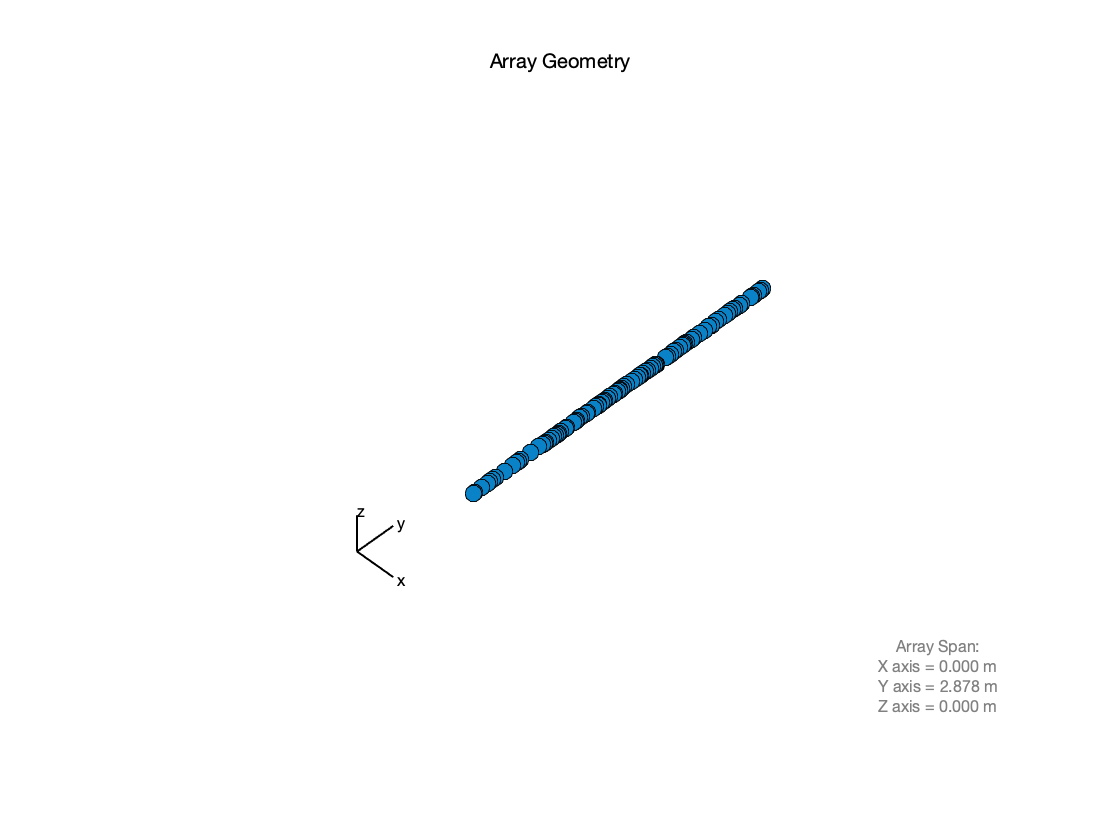


% % Results
% figure;
% semilogy(BestCosts,'LineWidth',2);
% xlabel('Iteration');
% ylabel('Best Cost');
% title('PSO Global Best Sidelobe diff (Bounding SL = -20dB)')

arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);GlobalBest.Position;zeros(1,N1)]);
viewArray(arr);


ula10g = phased.ULA(N1,lambda10g);
ula5g = phased.ULA(N1,lambda5g/2);
theta0 = 0; % scan angle
wd = steervec(getElementPosition(arr)/lambda5g,theta0);
cover = 20; % plot coverage angle
aperture = sort(GlobalBest.Position);
aperture = aperture(N1) - aperture(1);

p = pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c,'CoordinateSystem','rectangular','Type','powerdb','Weights',wd);
p = sort(findpeaks(p),'descend')'

p =          0  -19.4752  -19.4752  -19.4774  -19.4774  -19.4782  -19.4782  -19.4802  -19.4802  -19.4834  -19.4834  -19.4901  -19.4901  -19.5034  -19.5034  -19.5167  -19.5167  -19.5317  -19.5317  -19.5423  -19.5423  -19.5481  -19.5481  -19.5505  -19.5505  -19.5623  -19.5623  -19.5953  -19.5953  -19.6005  -19.6005  -19.6037  -19.6037  -19.6852  -19.6852  -19.6869  -19.6869  -19.7013  -19.7013  -19.7014  -19.7014  -19.7947  -19.7947  -19.8085  -19.8085  -19.8120  -19.8120  -19.9286  -19.9286  -19.9948


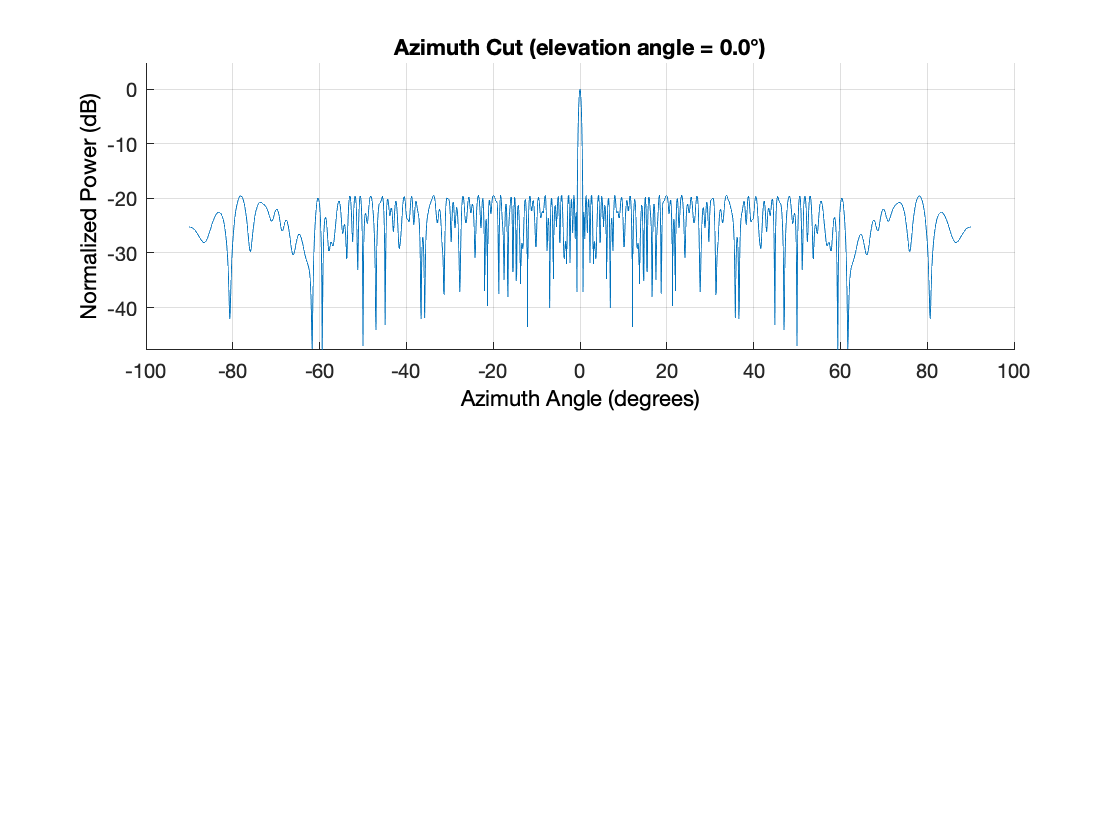


figure;
subplot(2,2,1:2)
hold on;
% save full 10g plot
pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)

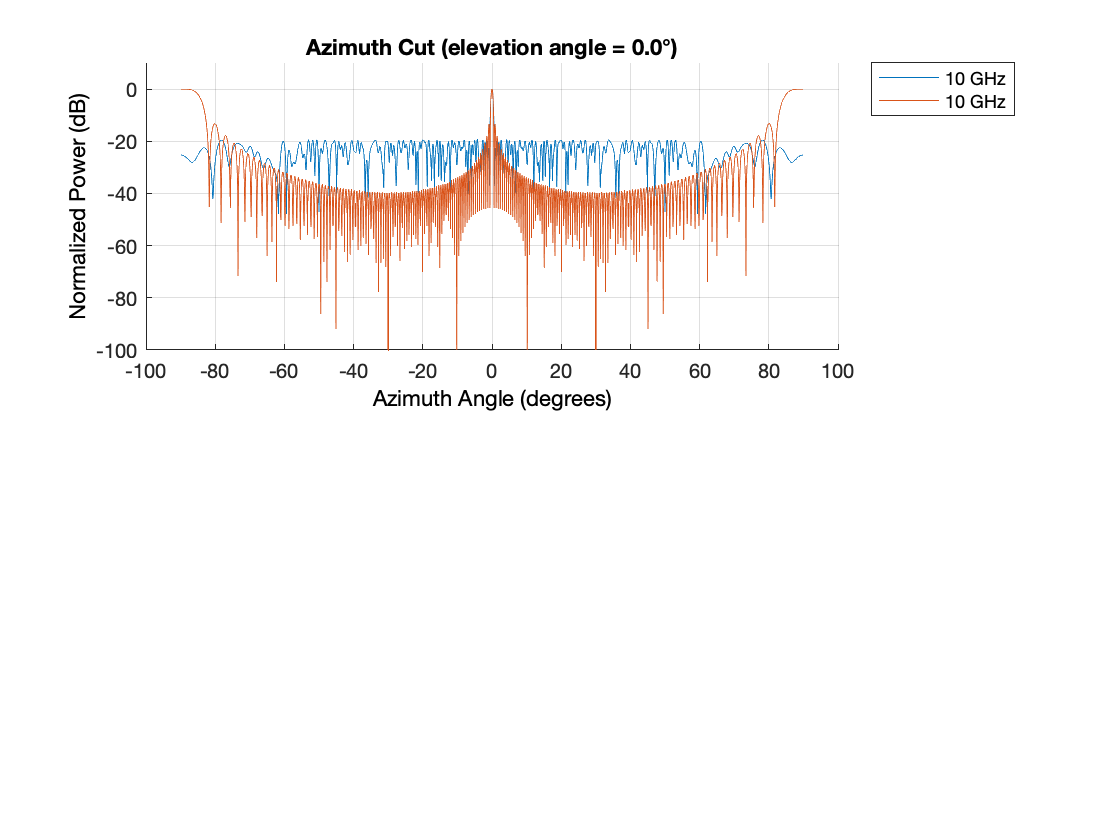

pattern(ula10g,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb')

title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);

Unrecognized function or variable 'L'.

legend(['Non-Uniform (N = ',num2str(N1),', Aperture = ',num2str(round(aperture*100,2)),'cm)'],...
    ['Uniform (N =',num2str(arrSize),', Aperture = ',num2str(len10g),'cm)'], ...
    'Location','south');
ylim([-40 5]);
hold off;


% ZOOMED FIGURE: 10G
subplot(2,2,3:4)
hold on;
pattern(arr,fc10g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)
pattern(ula10g,fc10g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform (N = ',num2str(N1),', Aperture = ',num2str(round(aperture*100,2)),'cm)'],...
    ['Uniform (N =',num2str(arrSize),', Aperture = ',num2str(len10g),'cm)'], ...
    'Location','south');
xlim([-cover cover]); ylim([-40 5]);
hold off;

figure;
subplot(2,2,1:2)
hold on;
% save full 5g plot
pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb','Weights',wd);
pattern(ula5g,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform Array (N = ',num2str(N1),', Aperture = ',num2str(round(aperture*100,2)),'cm)'],...
    ['Uniform Array (N =',num2str(arrSize),', Aperture = ',num2str(len5g),'cm)'], ...
    'Location','south');
ylim([-40 5]);
hold off;

% ZOOMED FIGURE: 5G
subplot(2,2,3:4)
hold on;
pattern(arr,fc5g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb','Weights',wd)
pattern(ula5g,fc5g,[-cover:.1:cover],0,'PropagationSpeed',c, ...
    'CoordinateSystem','rectangular','Type','powerdb')
title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
legend(['Non-Uniform Array (N = ',num2str(N1),', Aperture = ',num2str(round(aperture*100,2)),'cm)'],...
    ['Uniform Array (N =',num2str(arrSize),', Aperture = ',num2str(len5g),'cm)'], ...
    'Location','south');
xlim([-cover cover]); ylim([-40 5]);
hold off;

h = figure;
axis tight manual % this ensures that getframe() returns a consistent size
% filename = ['RLA_Non-Symmetric_',num2str(N1),'.gif'];
% filename = ['RLA_Symmetric_',num2str(N1),'.gif'];
filename = ['RLA_Gen',num2str(N1),'.gif'];
theta0 = -90:5:90;

for n = 1:size(theta0,2)
    % Calculate weight corrections to steer each freq.
    wd10 = steervec(getElementPosition(arr)/lambda10g,theta0(1,n));
    wd5 = steervec(getElementPosition(arr)/lambda5g,theta0(1,n));
    
    subplot(2,2,1:2)
    pattern(arr,fc10g,[-90:.1:90],0,'PropagationSpeed',c, ...
         'CoordinateSystem','rectangular','Type','powerdb','Weights',wd10);
    title(['Freq 10GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
    legend(['Non-Uniform (dAvg ~= lambda10g, N = ',num2str(N1),', Aperture = ',num2str(round(L*100,2)),'cm)'], ...
        'Location','south');
    xlim([-90 90]);
    ylim([-45 5]);
    
    subplot(2,2,3:4)
    pattern(arr,fc5g,[-90:.1:90],0,'PropagationSpeed',c, ...
        'CoordinateSystem','rectangular','Type','powerdb','Weights',wd5);
    title(['Freq 5GHz (Aperture(L) <= ',num2str(round(L*100,2)),'cm, N = ',num2str(N1),')']);
    legend(['Non-Uniform Array (dAvg ~= lambda5g/2, N = ',num2str(N1),', Aperture = ',num2str(round(L*100,2)),'cm)'], ...
        'Location','south');
    xlim([-90 90]);
    ylim([-45 5]);
    drawnow;
      % Capture the plot as an image 
      frame = getframe(h); 
      im = frame2im(frame); 
      [imind,cm] = rgb2ind(im,256); 
      % Write to the GIF File 
      if n == 1 
          imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
      else 
          imwrite(imind,cm,filename,'gif','WriteMode','append'); 
      end 
end